**Record an audio**

Human audible audio has a bandwidth of 20kHz. 

Sample audio at 44.1KHz or above for a few seconds. 

% sampleRate = 44.1e3; % Sampling frequency in KHz        
% duration = 5; % Time in seconds
% 
% recorder = audiorecorder(sampleRate, 24, 1);
% recorder.record(duration);
% pause(duration)
% 
% acquiredAudio = recorder.getaudiodata();

**OR**

**Load audio from file**

[acquiredAudio, sampleRate] = audioread('ayush.wav');
acquiredAudio = acquiredAudio(:,1); % Take only one channel for simplicity
soundsc(acquiredAudio,sampleRate);

**Initial processing**

Display the signal in time and frequency

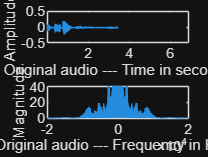

acquiredAudio = acquiredAudio(1:end+mod(numel(acquiredAudio), 2)-1); % Take odd number of samples for simplicity
sampPerFrame = numel(acquiredAudio);
audio_duration=length(acquiredAudio)/sampleRate;

audioSpectrum = fftshift(fft(acquiredAudio));% Compute the signal spectrum

time_array =  linspace(-audio_duration/2,audio_duration/2,sampPerFrame);% Compute the time array
frequency_array = linspace(-sampleRate/2, sampleRate/2, sampPerFrame);% Compute the frequency array

figure(1);
subplot(2,1,1);
plot(time_array, acquiredAudio);

axis([1/sampleRate sampPerFrame/sampleRate -0.5 0.5]);
xlabel('Original audio --- Time in seconds'); ylabel('Amplitude');

subplot(2,1,2);
plot(frequency_array, abs(audioSpectrum));
axis([-2e4 2e4 0 40]);
xlabel('Original audio --- Frequency in Hertz'); ylabel('Magnitude');


sound(acquiredAudio, sampleRate);

**Amplify audio**

Create an LTI system to amplify the signal to increase the volume and play the output audio.

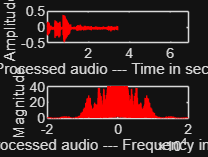

amplificationGain = 2;

 

processedAudio = amplificationGain*acquiredAudio;
processedAudioSpectrum = fftshift(fft(processedAudio));

sound(real(processedAudio), sampleRate);

figure(2);
subplot(2,1,1);
plot(time_array, real(processedAudio), 'r');
axis([1/sampleRate sampPerFrame/sampleRate -0.5 0.5]);
xlabel('Processed audio --- Time in seconds'); ylabel('Amplitude');

subplot(2,1,2);
plot(frequency_array, abs(processedAudioSpectrum), 'r');
axis([-2e4 2e4 0 40]);
xlabel('Processed audio --- Frequency in Hertz'); ylabel('Magnitude');

**Delay the audio**

Create an LTI system to delay the signal and play the output audio.

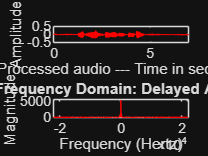

delayInSeconds =0.1;

 

delayInSamples = floor(delayInSeconds * sampleRate); % Convert seconds to number of samples
delayBuffer = zeros(delayInSamples, 1); % Create delay buffer with the correct size

processedAudio = [delayBuffer; acquiredAudio]; % Delay the signal by appending the buffer
processedAudioSpectrum = fftshift(fft(processedAudio)); % Compute the FFT of the delayed audio

sampPerFrame1 = length(processedAudio); % Correct length of the processed audio
time1 = (0:sampPerFrame1 - 1) / sampleRate; % Generate time array for plotting
frequency1 = linspace(-sampleRate / 2, sampleRate / 2, sampPerFrame1); % Frequency array for plotting

% Play the processed audio
sound(real(processedAudio), sampleRate);

% Plot the processed audio in time and frequency domains
figure(2);

% Time-domain plot
subplot(2, 1, 1);
plot(time1, real(processedAudio), 'r');
axis([0 max(time1) -0.5 0.5]); % Adjust x-axis based on the processed audio duration
xlabel('Processed audio --- Time in seconds'); ylabel('Amplitude');

% Frequency-domain plot
subplot(2, 1, 2);
plot(frequency1, abs(processedAudioSpectrum), 'r');
xlabel('Frequency (Hertz)');
ylabel('Magnitude');
title('Frequency Domain: Delayed Audio');

**Play audio fast/slow**

The audio can be played fast or slow by shrinking or expanding the signal in time, respectively. Perform this operation and play the output audio.

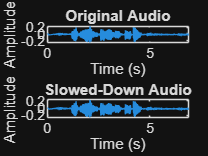

 
scalefactor =2.4;
% Convert scale factor to a fraction
[p, q] = rat(scalefactor, 1e-6); % Approximate to rational fraction

% Resample the audio to slow it down
processedAudio = resample(acquiredAudio, p, q);

% Adjust the sample rate for playback
newSampleRate = sampleRate * scalefactor;

% Play the slowed-down audio
sound(real(processedAudio), newSampleRate);

% Optional: Plot the original and processed audio
figure;
subplot(2, 1, 1);
timeOriginal = (0:length(acquiredAudio)-1) / sampleRate;
plot(timeOriginal, acquiredAudio);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Audio');

subplot(2, 1, 2);
timeProcessed = (0:length(processedAudio)-1) / newSampleRate;
plot(timeProcessed, processedAudio);
xlabel('Time (s)');
ylabel('Amplitude');
title('Slowed-Down Audio');

**Add echo to audio**

An echo can be added at *T* seconds by convolving the audio with another signal that has an impulse at 0 and *T* seconds. The impulse at *T* can have the amplitude equal to the required echo's amplitude.

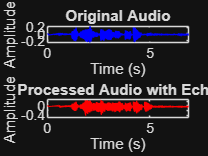

echoLocation =0.55;
echoGain = 1;

 

% Convert echo location to number of samples
delayInSamples = round(echoLocation * sampleRate);

% Create a delayed signal
delayBuffer = zeros(delayInSamples, 1); % Delay buffer
echoSignal = [delayBuffer; acquiredAudio * echoGain]; % Scaled delayed signal

% Ensure the echoSignal and acquiredAudio are of the same length
if length(echoSignal) > length(acquiredAudio)
    echoSignal = echoSignal(1:length(acquiredAudio));
else
    acquiredAudio = [acquiredAudio; zeros(length(echoSignal) - length(acquiredAudio), 1)];
end

% Add the original signal and the echo signal
processedAudio = acquiredAudio + echoSignal;

% Play the processed audio with echo
sound(real(processedAudio), sampleRate);

% Optional: Plot the original and processed audio
figure;
subplot(2, 1, 1);
timeOriginal = (0:length(acquiredAudio)-1) / sampleRate;
plot(timeOriginal, acquiredAudio, 'b');
xlabel('Time (s)');
ylabel('Amplitude');

title('Original Audio');

subplot(2, 1, 2);
timeProcessed = (0:length(processedAudio)-1) / sampleRate;
plot(timeProcessed, processedAudio, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Processed Audio with Echo');

**Audio equalizer (filter bank)**

The equalizer is a bank of LPF/HPF/BPF.

Create this filter-bank with the required cut-offs, gains and perform this filtering in the frequency domain (non-causal).

   

cutoff(1) = 0;
cutoff(2) = 300;
cutoff(3) = 1000;
cutoff(4) = 2000;
cutoff(5) = 4500;
cutoff(6) = 8000;
cutoff(7) = 12000;
cutoff(8) = 20000;

f(1) =3;
f(2) =2;
f(3) =0;
f(4) =0;
f(5) =0;
f(6) =0;
f(7) =0;



mask = (double(abs(frequency_array) <= cutoff(2)) * f(1))'

mask =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=3:8
    fil = double((cutoff(i-1) < abs(frequency_array)) & (abs(frequency_array) <= cutoff(i)))';
    mask = mask + fil*f(i-1);
end
new = audioSpectrum .* mask

new = 1.0e+04 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



processedAudio = real(ifft(ifftshift(new)))

processedAudio =    -0.0017
   -0.0012
   -0.0007
   -0.0003
    0.0000
    0.0002
    0.0003
    0.0004
    0.0004
    0.0003
    0.0001
   -0.0001
   -0.0003
   -0.0006
   -0.0009


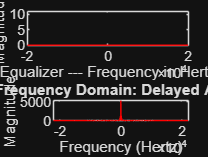

sound(real(processedAudio), sampleRate);

figure(2);
subplot(3,1,1);
plot(frequency_array, fftshift(abs(mask)), 'r');
axis([-2e4 2e4 0 11]);
xlabel('Equalizer --- Frequency in Hertz');
ylabel('Magnitude');

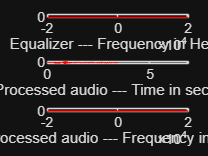


subplot(3,1,2);
plot(time_array, real(processedAudio(1:sampPerFrame)), 'r');
axis([0 sampPerFrame/sampleRate -0.5 0.5]);
xlabel('Processed audio --- Time in seconds');
ylabel('Amplitude');

processedAudioSpectrum = fft(processedAudio);
subplot(3,1,3);
plot(frequency_array, abs(processedAudioSpectrum), 'r');
axis([-2e4 2e4 0 40]);
xlabel('Processed audio --- Frequency in Hertz');
ylabel('Magnitude');

**Change pitch of audio**

The pitch of the audio can be shifted to a higher level by moving the positive frequency content to the right and the negative frequency content to the left by the same amount (vice versa for shifting to lower level).

Construct an LTI system to perform the pitch shift of the given audio.

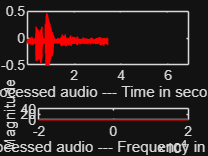

 

shiftPitchBy = -3;
shiftPitchByInHz = shiftPitchBy*1000;


sound(real(processedAudio), sampleRate);

figure(2);
subplot(2,1,1);
plot(time_array, real(processedAudio), 'r');
axis([1/sampleRate sampPerFrame/sampleRate -0.5 0.5]);
xlabel('Processed audio --- Time in seconds'); ylabel('Amplitude');

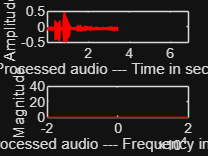


subplot(2,1,2);
plot(frequency_array, abs(processedAudioSpectrum), 'r');
axis([-2e4 2e4 0 40]);
xlabel('Processed audio --- Frequency in Hertz'); ylabel('Magnitude');

**For real-time audio use the following**

%--------Configure Parameters--------- 
sampleRate = 44100;      % >44.1k

Error using matlab.internal.capability.Capability.require (line 94)
This functionality is not available on remote platforms.

Error in audioDeviceReader

sampPerFrame = 2^16 + 1; % Odd number
duration = 5;


%--------Audio setup---------
deviceReader = audioDeviceReader(sampleRate,sampPerFrame);
setup(deviceReader);
time = (1:sampPerFrame)/sampleRate;
frequency = (((1-sampPerFrame)/2):((sampPerFrame-1)/2))*sampleRate/sampPerFrame;

deviceWriter = audioDeviceWriter(sampleRate);
setup(deviceWriter, zeros(sampPerFrame, 1));
%-----------------


%--------Processing setup---------
delayInSamples = floor(delayInSeconds*sampleRate);
delayBuffer = zeros(delayInSamples, 1);
lpf = (abs(frequency) <= cutoff).';
hpf = (abs(frequency) >= cutoff).';
%-----------------

%--------Real-time audio processing---------
t0 = datetime('now');
while seconds(datetime('now') - t0) < duration
    pause(0.001);

    acquiredAudio = deviceReader();
    audioSpectrum = fftshift(fft(acquiredAudio));

    %-----Process audio here-----
    
    
    
    
    % -------------
    
    subplot(4,1,1);
    plot(time_array, acquiredAudio);
    axis([1/sampleRate sampPerFrame/sampleRate -0.2 0.2]);
    xlabel('Original audio --- Time in seconds'); ylabel('Amplitude');

    subplot(4,1,2);
    plot(frequency_array, abs(audioSpectrum));
    axis([-2e4 2e4 0 40]);
    xlabel('Original audio --- Frequency in Hertz'); ylabel('Magnitude');

    subplot(4,1,3);
    plot(time_array, real(processedAudio), 'r');
    axis([1/sampleRate sampPerFrame/sampleRate -0.2 0.2]);
    xlabel('Processed audio --- Time in seconds'); ylabel('Amplitude');

    subplot(4,1,4);
    plot(frequency_array, abs(processedAudioSpectrum), 'r');
    axis([-2e4 2e4 0 40]);
    xlabel('Processed audio --- Frequency in Hertz'); ylabel('Magnitude');


    deviceWriter(real(processedAudio));
end


release(deviceReader);
release(deviceWriter);
